% Parameter estimation

S0 = 100; % Initial stock price
K = 100; % Strike price
B = 150; % Barrier level
r = 0.05; % Risk-free rate
T = 1; % Time to maturity (in years)
sigma = 0.2; % Volatility
rho = 0.5; % Correlation coefficient
N = 10000; % Number of simulations
M = 252; % Number of time steps

% Generate a grid for plotting
S0_values = linspace(50, 150, 20); % Varying initial stock prices
B_values = linspace(90, 150, 20); % Varying barrier levels
option_prices = zeros(length(S0_values), length(B_values));

%SDF

% Parameters
beta = 0.95;    % Discount factor
gamma = 2.0;    % Relative risk aversion coefficient

% Simulated consumption series (example)
C = [100, 105, 110, 108, 115];  % Consumption at different times

% Number of periods
n = length(C);

% Initialize SDF array
GS = zeros(1, n-1);

% Compute SDF for each period
for t = 1:n-1
    GS(t) = beta * (C(t+1) / C(t))^(-gamma);
end

% Display results
disp('Stochastic Discount Factors:')

Stochastic Discount Factors:


disp(GS)

    0.8617    0.8656    0.9855    0.8379



GS=mean(discount_factor)

GS = 0.8329


% Monte Carlo simulation with Gaussian copula
for i = 1:length(S0_values)
    for j = 1:length(B_values)
        S0 = S0_values(i);
        B = B_values(j);
        dt = T/M;
        %discount_factor = exp(-r*T);
        discount_factor = GS
        payoffs = zeros(N, 1);

        % Correlated normal random variables using Gaussian copula
        L = chol([1, rho; rho, 1], 'lower'); % Cholesky decomposition
        Z = randn(N, 2); % Independent standard normal random variables
        W = Z * L'; % Correlated random variables

        for k = 1:N
            S = S0;
            breached = false;

            for t = 1:M
                % Simulate correlated asset price path
                dS = (r - 0.5 * sigma^2) * dt + sigma * sqrt(dt) * W(k, 1);
                S = S * exp(dS);

                if S >= B
                    breached = true;
                    break;
                end
            end

            if ~breached
                payoffs(k) = max(S - K, 0); % Call option payoff
            end
        end

        option_price = discount_factor * mean(payoffs);
        option_prices(i, j) = option_price;
    end
end

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

discount_factor = 0.8329

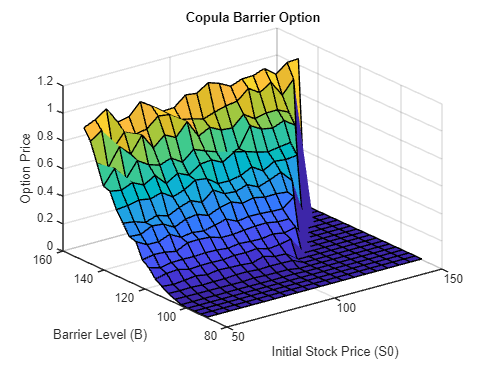


% Plotting the results
[X, Y] = meshgrid(S0_values, B_values);
surf(X, Y, option_prices')
xlabel('Initial Stock Price (S0)')
ylabel('Barrier Level (B)')
zlabel('Option Price')
title('Copula Barrier Option')